% =========================================================
% controlador_lqr.m
% Grupo G1 - Controle de Altitude de Drone
% UTFPR Apucarana - Analise de Sistemas Lineares 2026-1
% =========================================================

%clear; clc; close all;

%% 1. Definicao do Sistema (Espaco de Estados)
num = 0.8333;
den = [1 0.4167 0];
G = tf(num, den);

sys = ss(G);
A = sys.A;
B = sys.B;
C = sys.C(1, :);
D = 0;

disp('Matriz A:'), disp(A)

Matriz A:
   -0.4167         0
    0.5000         0



disp('Matriz B:'), disp(B)

Matriz B:
     1
     0



disp('Matriz C:'), disp(C)

Matriz C:
         0    1.6666



disp('Matriz D:'), disp(D)

Matriz D:
     0




%% 2. Verificacao de Controlabilidade
Co = ctrb(A, B);
posto = rank(Co);
fprintf('Posto da matriz de controlabilidade: %d\n', posto);

Posto da matriz de controlabilidade: 2


if posto == size(A,1)
    disp('Sistema totalmente controlavel. (Posto Cheio)');
else
    disp('ATENCAO: sistema NAO e controlavel.');
end

Sistema totalmente controlavel. (Posto Cheio)



%% 3. Projeto do Controlador LQR
Q = [10 0;
      0  1];
R = 0.1;
K = lqr(A, B, Q, R);
disp('Ganho K calculado:'), disp(K)

Ganho K calculado:
    9.7487    3.1623




fprintf('Polos da malha fechada (LQR):\n');

Polos da malha fechada (LQR):


p_mf = eig(A - B*K);
for i = 1:length(p_mf)
    fprintf('  p%d = %.4f + %.4fi\n', i, real(p_mf(i)), imag(p_mf(i)));
end

  p1 = -10.0074 + 0.0000i
  p2 = -0.1580 + 0.0000i


if all(real(p_mf) < 0)
    fprintf('Sistema em malha fechada: ESTAVEL\n');
else
    fprintf('ATENCAO: sistema instavel! Ajustar Q e R.\n');
end

Sistema em malha fechada: ESTAVEL



%% 4. Simulacao em Malha Fechada
% Ganho pre-filtro kr para rastreamento perfeito da referencia
% garante y(inf) = 1 para entrada degrau unitario
kr = -1 / (C * ((A - B*K) \ B));
fprintf('\nGanho pre-filtro kr = %.4f\n', kr);


Ganho pre-filtro kr = 1.8974



% Sistema em malha fechada
A_cl = A - B*K;
B_cl = B * kr;
sys_cl = ss(A_cl, B_cl, C, D);

% Vetor de tempo igual ao PID: 0 a 30s, passo 0.01s
% CORRECAO: original usava 0:0.01:10, incompativel com dados_pid.mat (3001 pontos)
t = (0:0.01:30)';
r = ones(size(t));

% Simulacao da altitude y(t)
[y_lqr, t_out, x] = lsim(sys_cl, r, t);
t = t_out;

% Sinal de controle u(t) = kr*r - K*x'
% x tem dimensao (3001 x 2), K tem dimensao (1 x 2)
% K*x' resulta em (1 x 3001), transpor para coluna
u_lqr = kr * r - (K * x')';

%% 5. Metricas de Desempenho
% CORRECAO: original usava sum()*dt (soma de Riemann)
% trapz() e mais preciso e consistente com controlador_pid.m
e_lqr = r - y_lqr;

RMSE = sqrt(mean(e_lqr.^2));
ISE  = trapz(t, e_lqr.^2);
IAE  = trapz(t, abs(e_lqr));
ITAE = trapz(t, t .* abs(e_lqr));

fprintf('\n=== Metricas de Desempenho - LQR ===\n');


=== Metricas de Desempenho - LQR ===


fprintf('  RMSE = %.6f\n', RMSE);

  RMSE = 0.330022


fprintf('  ISE  = %.6f\n', ISE);

  ISE  = 3.263527


fprintf('  IAE  = %.6f\n', IAE);

  IAE  = 6.372979


fprintf('  ITAE = %.6f\n', ITAE);

  ITAE = 38.660115


fprintf('Copiar esses valores para o Kauan montar a tabela comparativa.\n');

Copiar esses valores para o Kauan montar a tabela comparativa.



% Informacoes de resposta ao degrau
info = stepinfo(sys_cl);
fprintf('\n=== Informacoes de resposta ao degrau ===\n');


=== Informacoes de resposta ao degrau ===


fprintf('  Tempo de subida  (10-90%%): %.4f s\n', info.RiseTime);

  Tempo de subida  (10-90%): 13.9069 s


fprintf('  Tempo de pico:             %.4f s\n', info.PeakTime);

  Tempo de pico:             46.3442 s


fprintf('  Overshoot:                 %.4f %%\n', info.Overshoot);

  Overshoot:                 0.0000 %


fprintf('  Tempo de assentamento:     %.4f s\n', info.SettlingTime);

  Tempo de assentamento:     24.8623 s


fprintf('  Valor em regime permanente: %.4f\n', dcgain(sys_cl));

  Valor em regime permanente: 1.0000


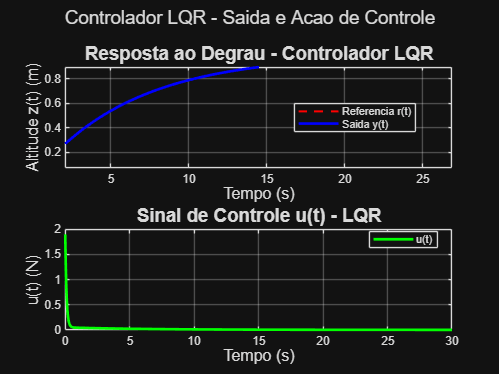


%% 6. Plots
figure(1);
subplot(2,1,1);
plot(t, r, 'r--', 'LineWidth', 1.5); hold on;
plot(t, y_lqr, 'b-', 'LineWidth', 2); hold off;
title('Resposta ao Degrau - Controlador LQR', 'FontSize', 14);
xlabel('Tempo (s)', 'FontSize', 12);
ylabel('Altitude z(t) (m)', 'FontSize', 12);
legend('Referencia r(t)', 'Saida y(t)', 'Location', 'best');
grid on;

subplot(2,1,2);
plot(t, u_lqr, 'g-', 'LineWidth', 2);
title('Sinal de Controle u(t) - LQR', 'FontSize', 14);
xlabel('Tempo (s)', 'FontSize', 12);
ylabel('u(t) (N)', 'FontSize', 12);
legend('u(t)', 'Location', 'best');
grid on;

sgtitle('Controlador LQR - Saida e Acao de Controle', 'FontSize', 14);


%% 7. Salvar dados para espectrograma
save('dados_lqr.mat', 'u_lqr', 't', 'y_lqr', 'e_lqr', 'K', 'kr', 'RMSE', 'ISE', 'IAE', 'ITAE');
fprintf('\nVariaveis salvas em dados_lqr.mat para uso no espectrograma.\n');


Variaveis salvas em dados_lqr.mat para uso no espectrograma.


fprintf('Salvar figuras:\n');

Salvar figuras:


fprintf('  fig_lqr_subplot.png  (Figura 1) — 600 dpi\n');

  fig_lqr_subplot.png  (Figura 1) — 600 dpi
